# INIT FILE DYNAMIC SIMULATION

clc; close all; clear;

#### Simulation time set-up:

T_sim = 600;              % simulation time [s]
dT = 0.1;                 % time interval [s]
time = 0:dT:T_sim;        % time vector [s]

#### DTU 10 MW data:

rho_air = 1.225;          % air density [kg/m3]
R_rotor = 178.3/2;        % rotor radius [m]
A_rotor = pi*R_rotor^2;   % rotor area [m2]
V_rated = 11.4;           % rated wind speed [m/s]
V_ci = 4;                 % cut-in wind speed [m/s]
V_co = 25;                % cut-out wind speed [m/s]
Jeq = 1.56e8;             % equivalent inertia [kg*m2]
b = 2e5;                  % damping coefficient [N*m*s/rad]
omega_fixed = 0.78;       % fixed rotating speed [rad/s]
n_switch = 0;

#### Cp optimal, Lambda optimal and Rated Torque

lambda_sweep = (2.0:0.1:12.8)';          % tip speed ratio axis from 2.0 to 12.8 []    
% EXPONENTIAL FITTING FORMULA
Cp_curve = PowerFactor(lambda_sweep, 0);
Cp_opt = max(Cp_curve); % Optimal Cp (the highest on the curve)
lambda_opt = lambda_sweep(find(~(Cp_curve - max(Cp_curve)))); %#ok<FNDSB> % Optimal tip speed ratio
Trated = Cp_opt / lambda_opt * 0.5 * rho_air * A_rotor .* V_rated^2 * R_rotor;

#### Sumulation with RAMP wind profile:

%% -- SETUP of the wind velocity (min = 0.18, max = 37.71).
Vw_ramp = 0.18 + ((V_co + 12.71)/T_sim) * time;
Vw_in = Vw_ramp;

%%try different values
omega_rotor_0 = Vw_ramp(1)*lambda_opt/R_rotor; % initial condition (initial rotor speed)

## SIMULATION STALL REGULATED

### Extract Power data from the simulation

Simulink.fileGenControl('set', 'CacheFolder', '/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/C_Stall Regulated');
Simulink.fileGenControl('set', 'CodeGenFolder', '/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/C_Stall Regulated');

stallOut = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/C_Stall Regulated/Stall_regulated_sim.slx');
P_sim_stall = stallOut.P_gen / 1e6;

### STALL Simulated vs Numerical Results

#### Generate the Numerical power curve

V_w = linspace(0.18, 37.71, 100); % wind velocity has min = 0.18, max = 37.71
P_wind = 1/2 * rho_air * A_rotor * V_w.^3;
lambda_fixed = omega_fixed * R_rotor ./ V_w;
P_num_stall = P_wind .* PowerFactor(lambda_fixed, 0); 
P_num_stall(V_w < 5.5 | V_w > V_co) = 0; % As calculated in the static analisys

#### Plot the comparison between Simulated and Numerical curves

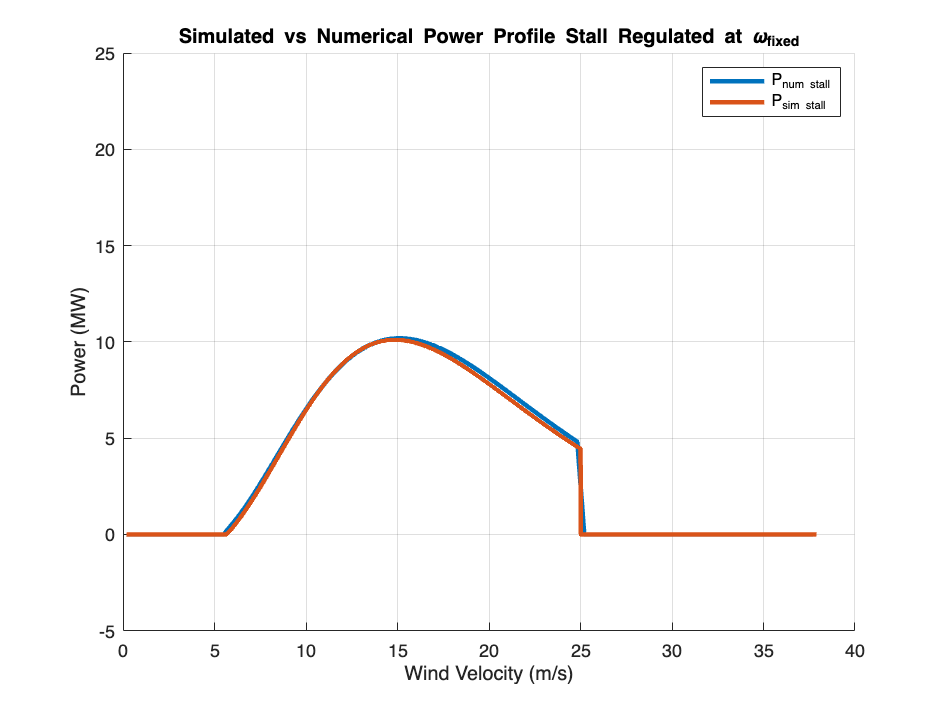

i = 1;
figure(i);
hold on
grid on
% Numerical 
plot(V_w,P_num_stall / 1e6, 'Color', [0, 0.4470, 0.7410], 'LineWidth', 2.5)
% Simulated
plot(Vw_ramp, P_sim_stall,'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 2.5)

xlabel('Wind Velocity (m/s)');
ylabel('Power (MW)');
title('Simulated vs Numerical Power Profile Stall Regulated at \omega_{fixed}')
ylim([-5 25])
legend('P_{num stall}', 'P_{sim stall}');
hold off

## SIMULATION PITCH REGULATED

Simulink.fileGenControl('set', 'CacheFolder', '/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/D_Pitch Regulated');
Simulink.fileGenControl('set', 'CodeGenFolder', '/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/D_Pitch Regulated');
noise = 0 * randn(size(time));  % Noise = 0, will be introduced later
Vw_noisy = noise;

pitchOut = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/D_Pitch Regulated/Pitch_regulated_sim.slx');
P_sim_pitch = pitchOut.P_gen / 1e6;

### PITCH Simulated vs Numerical Results

#### Generate the Numerical power curve

V_w = linspace(0.18, 37.71, 100);
P_wind = 1/2 * rho_air * A_rotor * V_w.^3;
omega_fixed = 0.78; % Taken by the static analisys
lambda_fixed = omega_fixed * R_rotor ./ V_w;

#### Potenza Turbina calcolata Numericamente

Prated = 1/2 * rho_air * A_rotor * V_rated^3 * Cp_opt;
% Working Regions 
I1 = find(V_w<V_ci);
I2 = find(V_w>=V_ci & V_w<=V_rated);
I3 = find(V_w>V_rated & V_w<=V_co);
I4 = find(V_w>V_co);

P_num_pitch = 0*V_w;
P_num_pitch(I2) = 0.5*rho_air*V_w(I2).^3*A_rotor*Cp_opt;
P_num_pitch(I3) = Prated; 

#### Plot the comparison between Simulated and Numerical curves

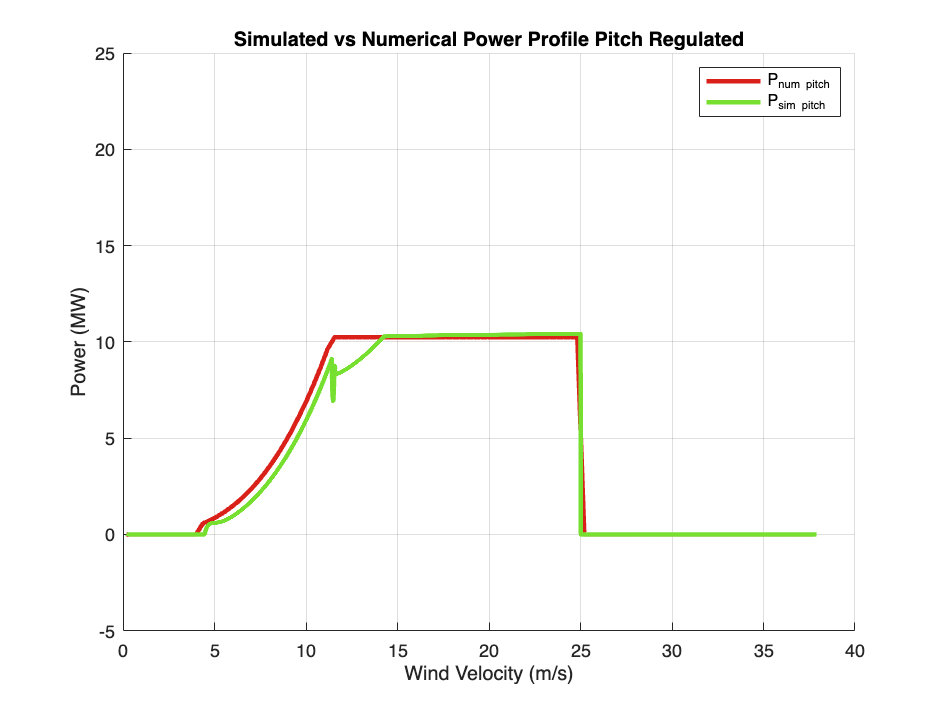

i = i + 1;
figure(i);
hold on
grid on
% Numerical 
plot(V_w,P_num_pitch / 1e6, 'Color', [0.8500, 0.1250, 0.0980], 'LineWidth', 2.5)
% Simulated
plot(Vw_ramp, P_sim_pitch,'Color', [0.4660, 0.8740, 0.1880], 'LineWidth', 2.5)

xlabel('Wind Velocity (m/s)');
ylabel('Power (MW)');
title('Simulated vs Numerical Power Profile Pitch Regulated')
ylim([-5 25])
legend('P_{num pitch}', 'P_{sim pitch}');
hold off

pitchAvg = mean(P_sim_pitch)

pitchAvg = 4.2617

## KAIMAL WIND DISTRIBUTION

The wind turbolance intensity is on the order of 10%. The velocities that will be used are the 25th, the 50th and the 75th percentile and a perturbation around the 90% of the cut out velocity. 

Wind_data = '/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/Wind_data.csv';
data = readtable(Wind_data, 'VariableNamingRule', 'preserve');
sample_data = data.("Wind speed (m/s)");

% Filtraggio dei dati del vento
v_wind = sample_data(~isnan(sample_data) & ~isinf(sample_data) & sample_data >= 0);

% Velocità significative
Vw_mean = mean(v_wind);              % Mean velocity of the wind
Vw_25 = quantile(v_wind, 0.25);      % 25° percentile
Vw_50= quantile(v_wind, 0.50);       % 50° percentile (mediana)
Vw_75 = quantile(v_wind, 0.75);      % 75° percentile
Vw_90 = 25 * 0.9;                    % 90% of Cut-out velocity

%% Spettro Kaimal
I = 0.02;                   % Intensità del vento (tipica 15%)
L = 600;                    % Lunghezza caratteristica [m]

% Parametri dello spettro
N_freq = 100;               % Numero di frequenze
f_n = linspace(0.01, 2, N_freq); % Frequenze (0.01 Hz - 2 Hz)
phi_n = 2 * pi * rand(1, N_freq); % Fasi casuali [rad]

### 25th Percentile wind velocity power profile

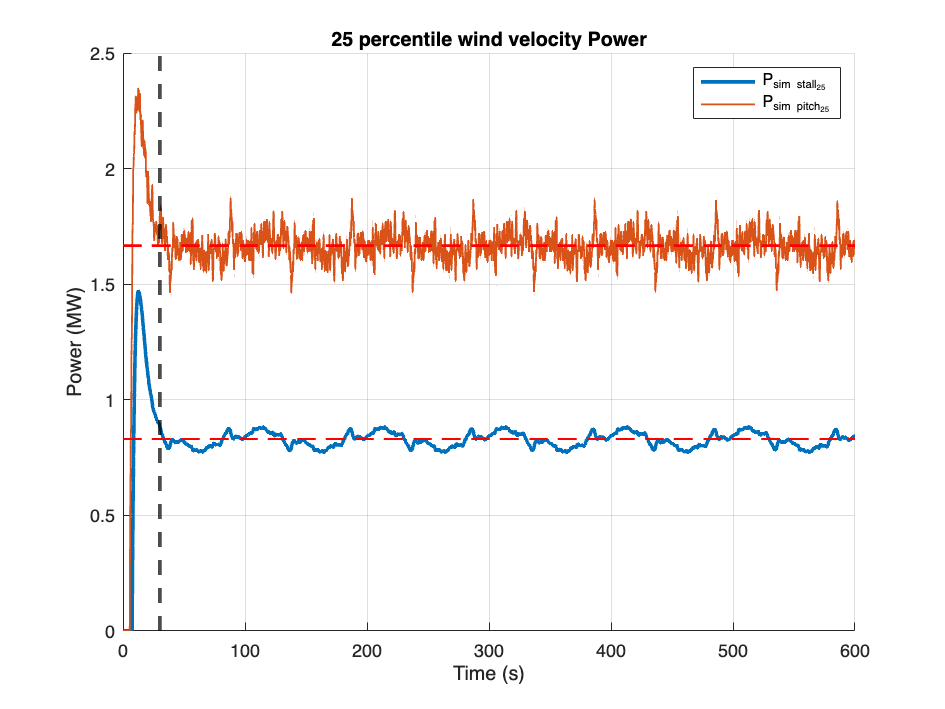

%% Calcolo del segnale v(t) per v_25
Vw_t_25 = Kaimal(Vw_25, I, L, N_freq, f_n, phi_n, time, T_sim);
Vw_in  = Vw_t_25;

% Stall Power 25
stallOut_25 = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/C_Stall Regulated/Stall_regulated_sim.slx');
P_sim_stall_25 = stallOut_25.P_gen / 1e6;

% Pitch Power 25
pitchOut_25 = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/D_Pitch Regulated/Pitch_regulated_sim.slx');
P_sim_pitch_25 = pitchOut_25.P_gen / 1e6;

% Mean Values 25
P_mean_stall_25 = mean(P_sim_stall_25(31:end));
P_mean_pitch_25 = mean(P_sim_pitch_25(31:end));

i = i + 1;
figure(i);
hold on
grid on
plot(time, P_sim_stall_25,'Color', [0, 0.4470, 0.7410], 'LineWidth', 2)
plot(time, P_sim_pitch_25,'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1)
plot(time, ones(size(time)) * P_mean_stall_25, '--k', 'Color', 'Red', 'LineWidth', 1.5)
plot(time, ones(size(time)) * P_mean_pitch_25, '--k', 'Color', 'Red', 'LineWidth', 1.5)
xline(30, '--k', 'LineWidth', 2);


xlabel('Time (s)');
ylabel('Power (MW)');
title('25 percentile wind velocity Power')
legend('P_{sim stall_{25}}', 'P_{sim pitch_{25}}');
hold off

Mean_diff_25 = P_mean_pitch_25 - P_mean_stall_25;
display(P_mean_pitch_25);

P_mean_pitch_25 = 1.6666

display(P_mean_pitch_25/P_mean_stall_25*100);

  200.7149



### 50th Percentile wind velocity power profile

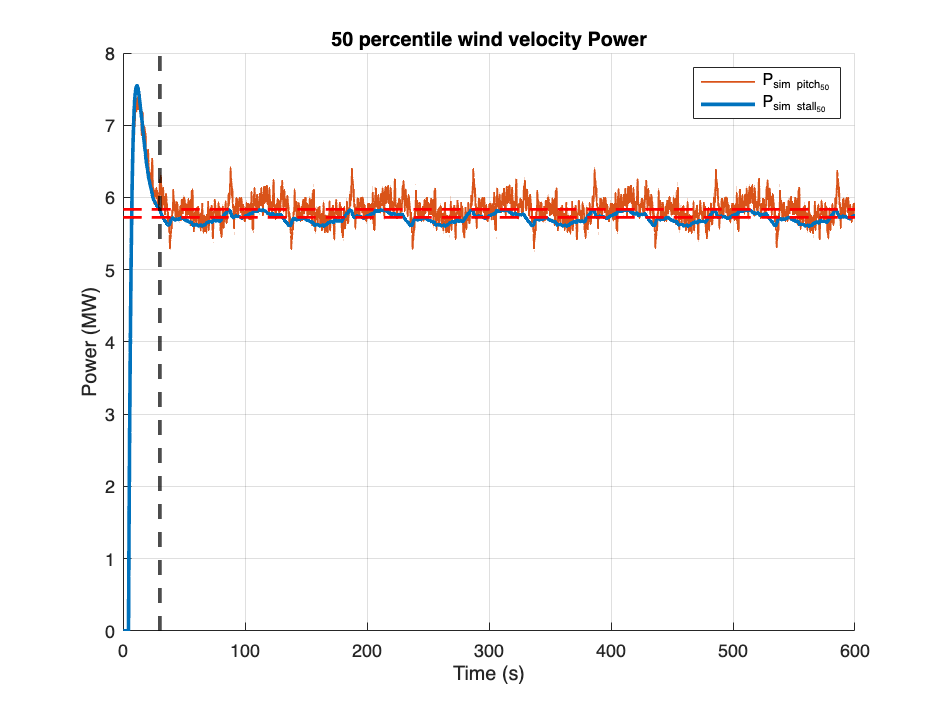

%% Calcolo del segnale v(t) per v_25
Vw_t_50 = Kaimal(Vw_50, I, L, N_freq, f_n, phi_n, time, T_sim);
Vw_in  = Vw_t_50;

% Stall Power 50
stallOut_50 = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/C_Stall Regulated/Stall_regulated_sim.slx');
P_sim_stall_50 = stallOut_50.P_gen / 1e6;

% Pitch Power 50
pitchOut_50 = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/D_Pitch Regulated/Pitch_regulated_sim.slx');
P_sim_pitch_50 = pitchOut_50.P_gen / 1e6;

% Mean Values 50
P_mean_stall_50 = mean(P_sim_stall_50(31:end));
P_mean_pitch_50 = mean(P_sim_pitch_50(31:end));

i = i + 1;
figure(i);
hold on
grid on
plot(time, P_sim_pitch_50,'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1)
plot(time, P_sim_stall_50,'Color', [0, 0.4470, 0.7410], 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_pitch_50, '--k', 'Color', 'Red', 'LineWidth', 1.5)
plot(time, ones(size(time)) * P_mean_stall_50, '--k', 'Color', 'Red', 'LineWidth', 1.5)
xline(30, '--k', 'LineWidth', 2);


xlabel('Time (s)');
ylabel('Power (MW)');
title('50 percentile wind velocity Power')
legend('P_{sim pitch_{50}}', 'P_{sim stall_{50}}');
hold off

Mean_diff_50 = P_mean_pitch_50 - P_mean_stall_50;
display(Mean_diff_50);

Mean_diff_50 = 0.1111

display(P_mean_pitch_50/P_mean_stall_50*100);

  101.9399



### Mean Percentile wind velocity power profile

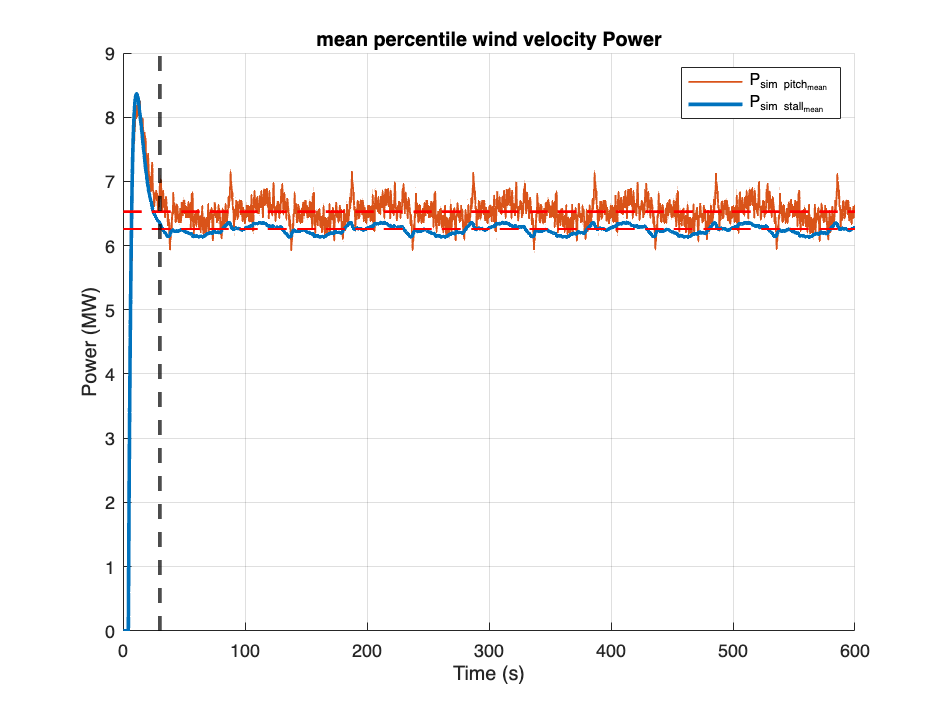

%% Calcolo del segnale v(t) per Vw_mean
Vw_t_mean = Kaimal(Vw_mean, I, L, N_freq, f_n, phi_n, time, T_sim);
Vw_in  = Vw_t_mean;

% Stall Power mean
stallOut_mean = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/C_Stall Regulated/Stall_regulated_sim.slx');
P_sim_stall_mean = stallOut_mean.P_gen / 1e6;

% Pitch Power mean
pitchOut_mean = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/D_Pitch Regulated/Pitch_regulated_sim.slx');
P_sim_pitch_mean = pitchOut_mean.P_gen / 1e6;

% Mean Values mean
P_mean_stall_mean = mean(P_sim_stall_mean(31:end));
P_mean_pitch_mean = mean(P_sim_pitch_mean(31:end));

i = i + 1;
figure(i);
hold on
grid on
plot(time, P_sim_pitch_mean,'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1)
plot(time, P_sim_stall_mean,'Color', [0, 0.4470, 0.7410], 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_pitch_mean, '--k', 'Color', 'Red', 'LineWidth', 1.5)
plot(time, ones(size(time)) * P_mean_stall_mean, '--k', 'Color', 'Red', 'LineWidth', 1.5)
xline(30, '--k', 'LineWidth', 2);


xlabel('Time (s)');
ylabel('Power (MW)');
title('mean percentile wind velocity Power')
legend('P_{sim pitch_{mean}}', 'P_{sim stall_{mean}}');
hold off

Mean_diff_mean = P_mean_pitch_mean - P_mean_stall_mean;
display(Mean_diff_mean);

Mean_diff_mean = 0.2701

display(P_mean_pitch_mean/P_mean_stall_mean*100);

  104.3154



### 0.9 of the Cut-out velocity

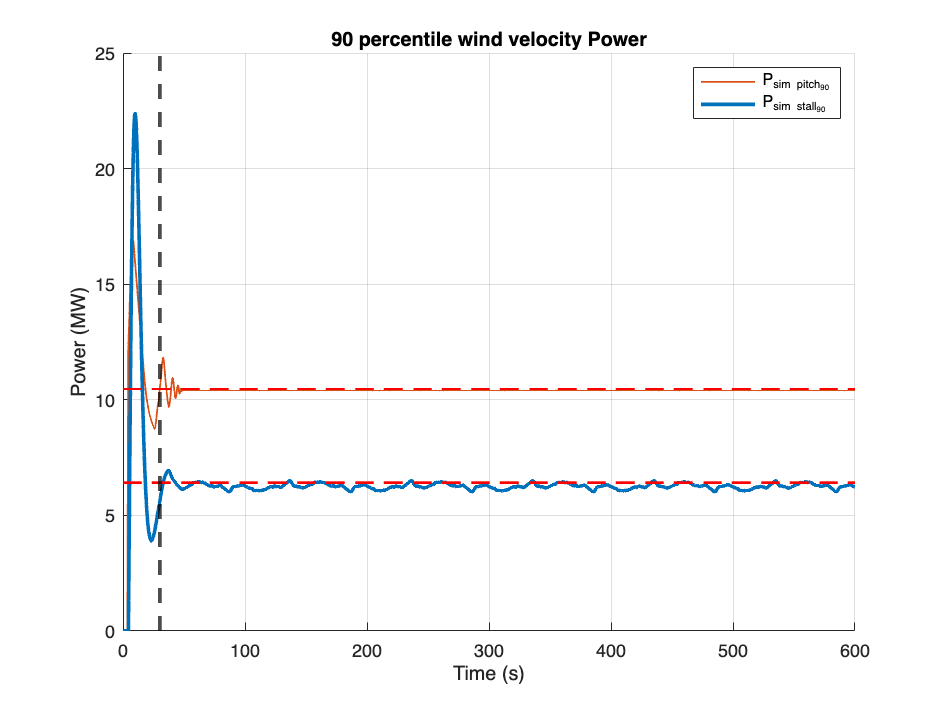

%% Calcolo del segnale v(t) per Vw_90
Vw_t_90 = Kaimal(Vw_90, I, L, N_freq, f_n, phi_n, time, T_sim);
Vw_in  = Vw_t_90;

% Stall Power 90
stallOut_90 = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/C_Stall Regulated/Stall_regulated_sim.slx');
P_sim_stall_90 = stallOut_90.P_gen / 1e6;

% Pitch Power 90
pitchOut_90 = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/D_Pitch Regulated/Pitch_regulated_sim.slx');
P_sim_pitch_90 = pitchOut_90.P_gen / 1e6;

% 90 Values 90
P_mean_stall_90 = mean(P_sim_stall_90(31:end));
P_mean_pitch_90 = mean(P_sim_pitch_90(31:end));

i = i + 1;
figure(i);
hold on
grid on
plot(time, P_sim_pitch_90,'Color', [0.8500, 0.3250, 0.0980], 'LineWidth', 1)
plot(time, P_sim_stall_90,'Color', [0, 0.4470, 0.7410], 'LineWidth', 2)
plot(time, ones(size(time)) * P_mean_pitch_90, '--k', 'Color', 'Red', 'LineWidth', 1.5)
plot(time, ones(size(time)) * P_mean_stall_90, '--k', 'Color', 'Red', 'LineWidth', 1.5)
xline(30, '--k', 'LineWidth', 2);


xlabel('Time (s)');
ylabel('Power (MW)');
title('90 percentile wind velocity Power')
legend('P_{sim pitch_{90}}', 'P_{sim stall_{90}}');
hold off

Mean_diff_90 = P_mean_pitch_90 - P_mean_stall_90;
display(Mean_diff_90);

Mean_diff_90 = 4.0508

display(P_mean_pitch_90/P_mean_stall_90*100);

  163.2328



## NOISE INTRODUCTION ON THE ANEMOMETER

Assume that the anemometer of the pitch control system is affected by a noise. The noise introduces a standard deviation of 0.5.

n_switch = 1;
% Adding noise similar to that of an anemometer
noise_std = 0.5;           % Standard deviation of noise [m/s]
noise = noise_std * randn(size(time));  % Random noise

Vw_noisy = Vw_ramp + noise;
Vw_in = Vw_ramp;


Sim_noise = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/D_Pitch Regulated/Pitch_regulated_sim.slx');
pitchOut_noise = Sim_noise.P_gen;
pitchAvg_noise = mean(pitchOut_noise)

pitchAvg_noise = 4.2336e+06


noise_efficiency = pitchAvg_noise / pitchAvg

noise_efficiency = 9.9341e+05

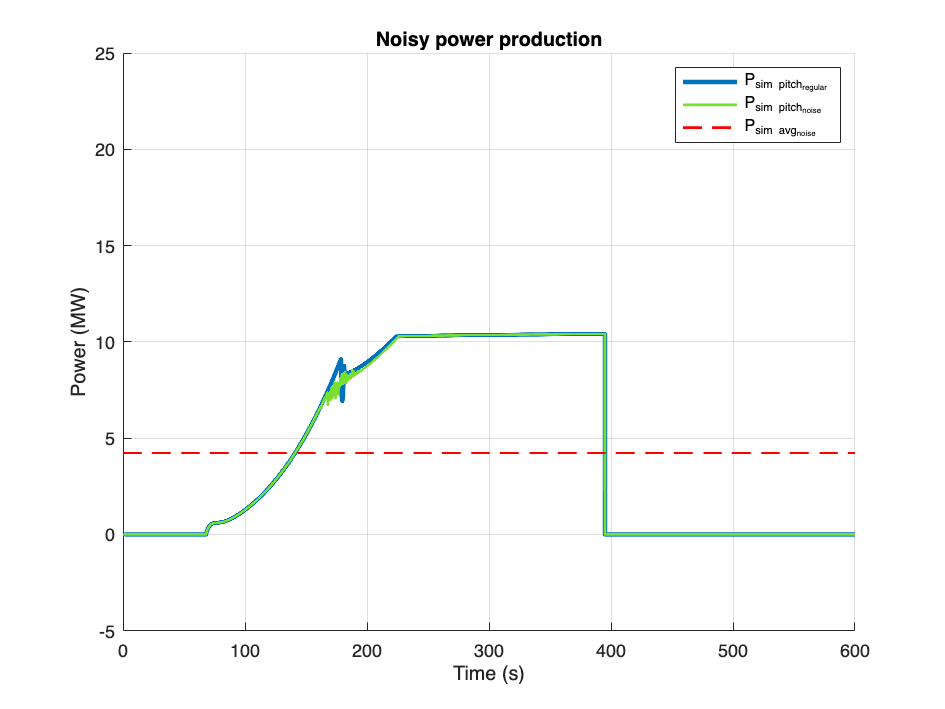

i = i + 1;
figure(i);
hold on
grid on
plot(time, P_sim_pitch,'Color', [0, 0.4470, 0.7410], 'LineWidth', 2.5)
plot(time, (pitchOut_noise)/1e6,'Color', [0.4660, 0.8740, 0.1880], 'LineWidth', 1.5)
plot(time, (ones(size(time)) * pitchAvg_noise)/1e6, '--k', 'Color', 'Red', 'LineWidth', 1.5)
ylim([-5 25])
xlabel('Time (s)');
ylabel('Power (MW)');
title('Noisy power production')
legend('P_{sim pitch_{regular}}', 'P_{sim pitch_{noise}}', 'P_{sim avg_{noise}}');
hold off

#### Simulate noise around wind speed of 12 m/s:

Vw_noisy = 12 * ones(size(time)) + noise;
Vw_in = 12 * ones(size(time));

Sim_noise = sim('/Users/edoardomurgia/Università/Mechatronics Engineering/2° Anno/Primo Semestre/Renewable Energies/Homework 1/D_Pitch Regulated/Pitch_regulated_sim.slx');
pitchOut_noise = Sim_noise.P_gen;
pitchAvg_noise = mean(pitchOut_noise)

pitchAvg_noise = 9.1658e+06

noise_efficiency = pitchAvg_noise / pitchAvg

noise_efficiency = 2.1507e+06

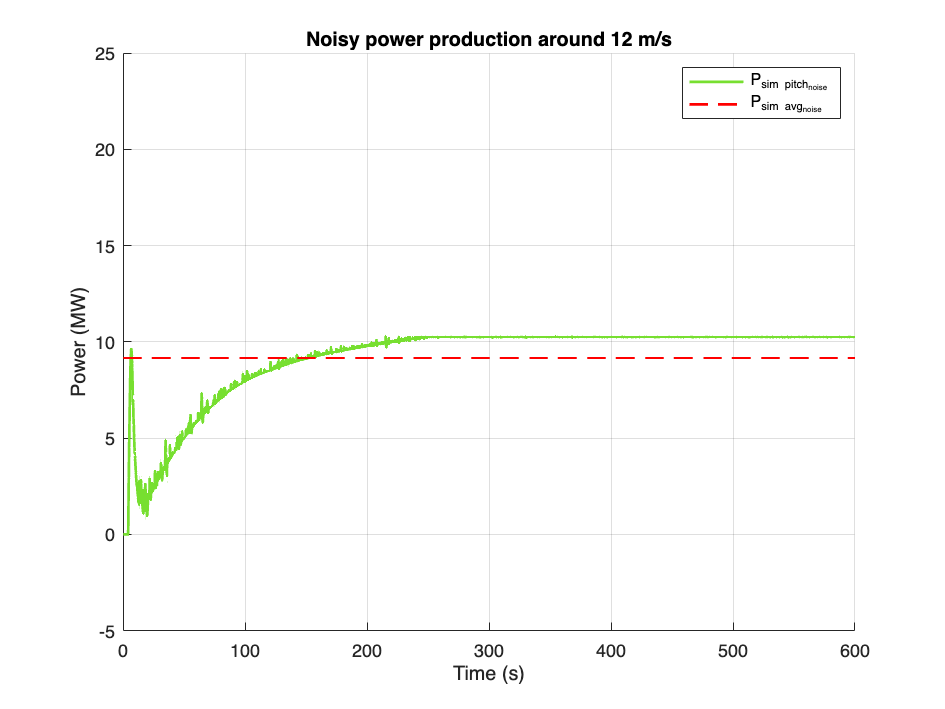

i = i + 1;
figure(i);
hold on
grid on
plot(time, (pitchOut_noise)/1e6,'Color', [0.4660, 0.8740, 0.1880], 'LineWidth', 1.5)
plot(time, (ones(size(time)) * pitchAvg_noise)/1e6, '--k', 'Color', 'Red', 'LineWidth', 1.5)
ylim([-5 25])
xlabel('Time (s)');
ylabel('Power (MW)');
title('Noisy power production around 12 m/s')
legend('P_{sim pitch_{noise}}', 'P_{sim avg_{noise}}');
hold off